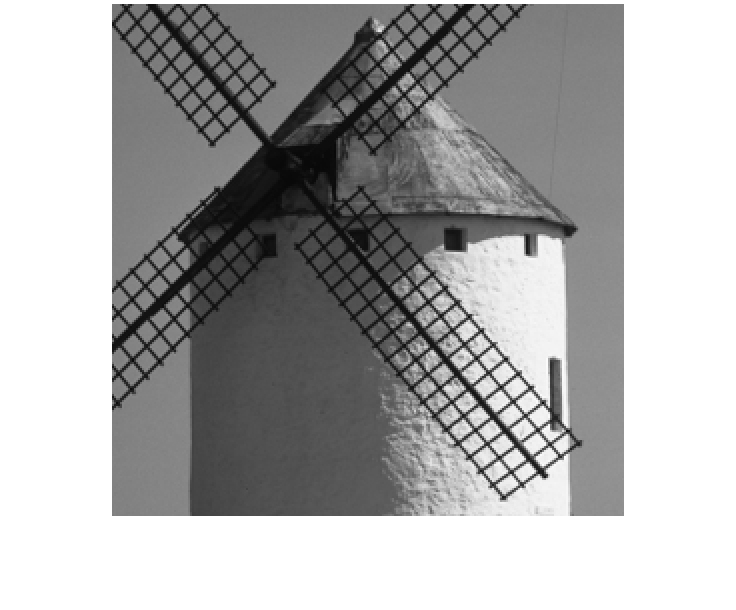

%1.0
bild = imread('kvarn.tif');
bild = double(bild)/255;

imshow(bild)

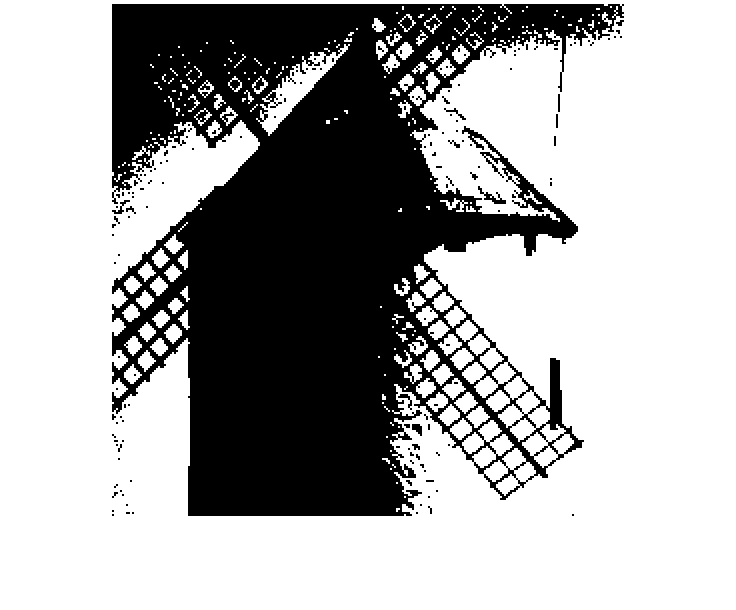

% 1.1
b11 = bild>0.5;

imshow(b11)


%svar 2

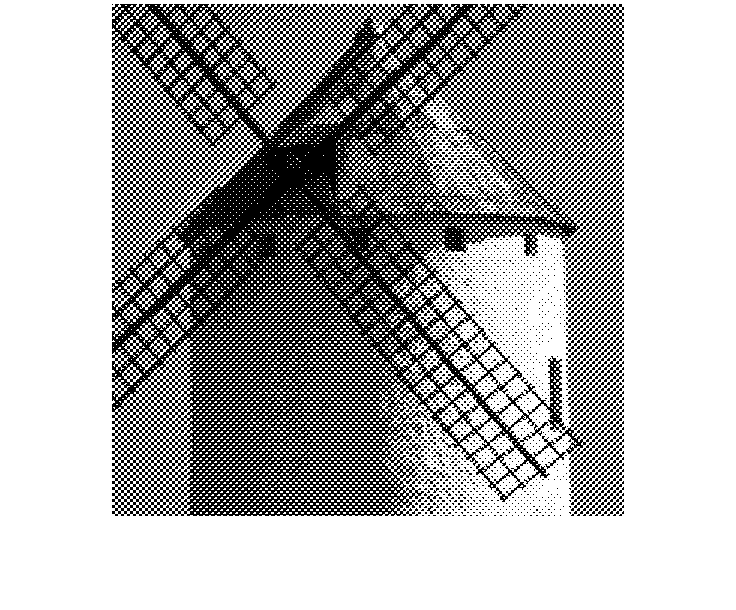

%1.2
load troskelmatriser.mat;
bild = imread('kvarn.tif');
bild = double(bild)/255;
tr1;
normtr1 = tr1/19;
%svar 19
tr2;
normtr2 = tr2/33;
%svar 33
b12_tr1 = troskel(bild,normtr1);
b12_tr2 = troskel(bild,normtr2);
imshow(b12_tr1) 

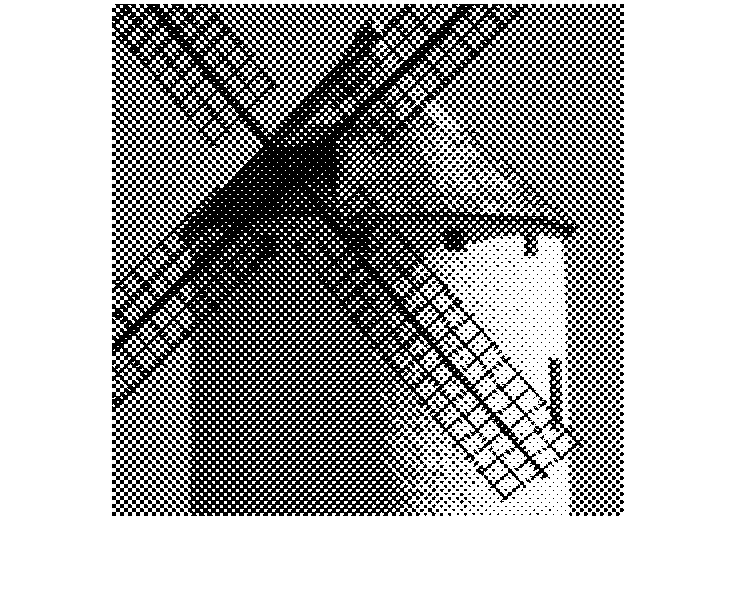

imshow(b12_tr2) 

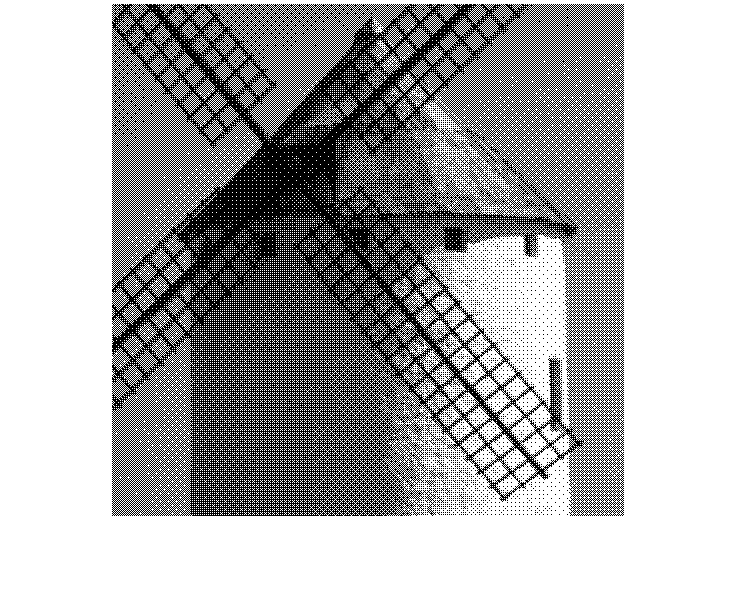

% 1.3
% svar 33
normtr3 = tr3/33;

b13= troskel(bild,normtr3);
imshow(b13) ;

% svar tr3 är splittrad medan tr2 är sluten. tr3 ger inget upprepande
% mönster och visas därför varierad och mer lik orginalet

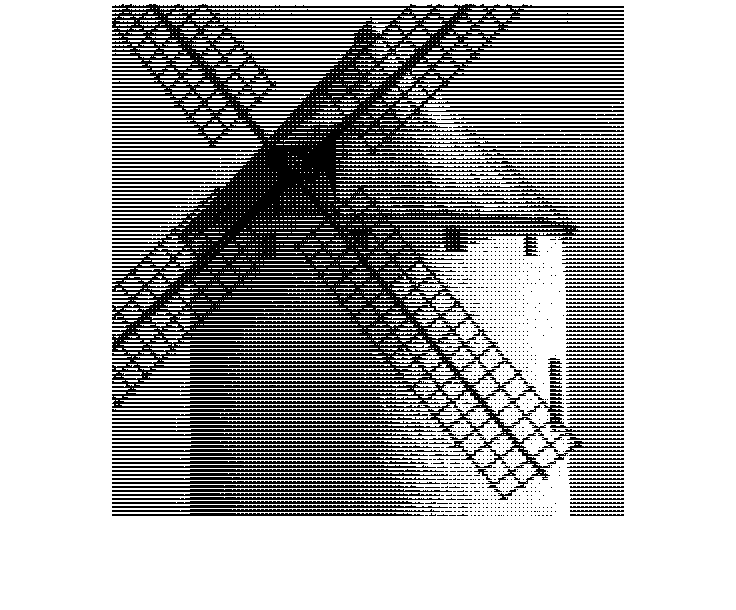

% %1.4
linjeM = [1 2 3 4; 5 6 7 8; 9 10 11 12; 13 14 15 16];
spiralM = [7 8 9 10; 6 1 2 11; 5 4 3 12; 16 15 14 13];
NlinjeM = linjeM/17;
NspiralM = spiralM/17;

b41 = troskel(bild,NlinjeM);
imshow(b41);

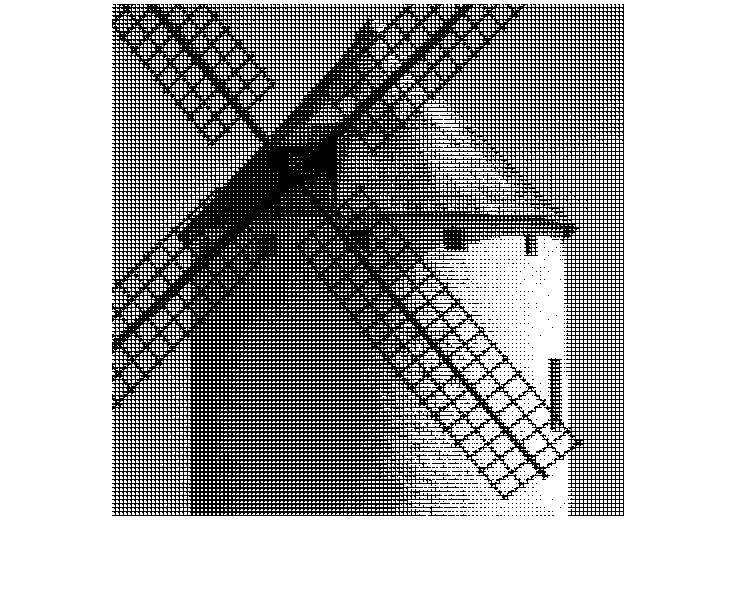

b42 = troskel(bild,NspiralM);
imshow(b42);

%1.5
%högre värde på tröskelmatrisernas storlek leder till fler
%rasterpunkter i höjd och bredd.

%1.6
% det är alltid det största tröskelvärdet plus ett. (eftersom att man ska
% inkludera noll)

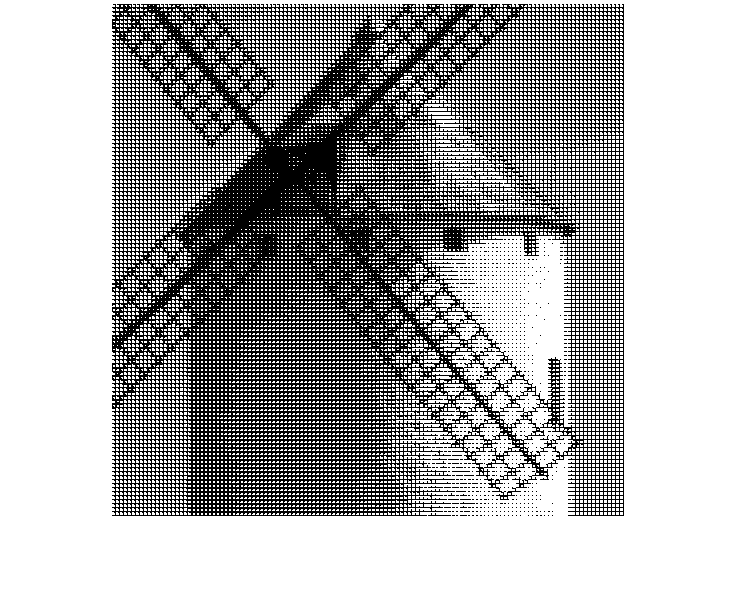

%2.1
b21 = tabellrast(bild);
imshow(b21);


%innehåller 2 grånivåer, 0 och 1.

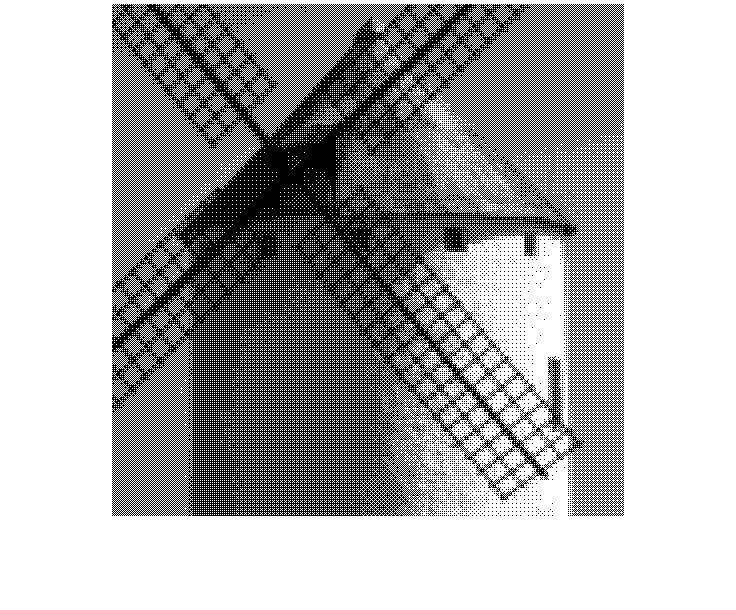

%2.2
b22 = tabellrast2(bild);
imshow(b22);

b22

b22 = 512×512 logical array
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0
   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   1   0   1   0   1   0
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0

%2.3
% b21 använder linjära halftoner medan b22 använder cirkulära halftoner

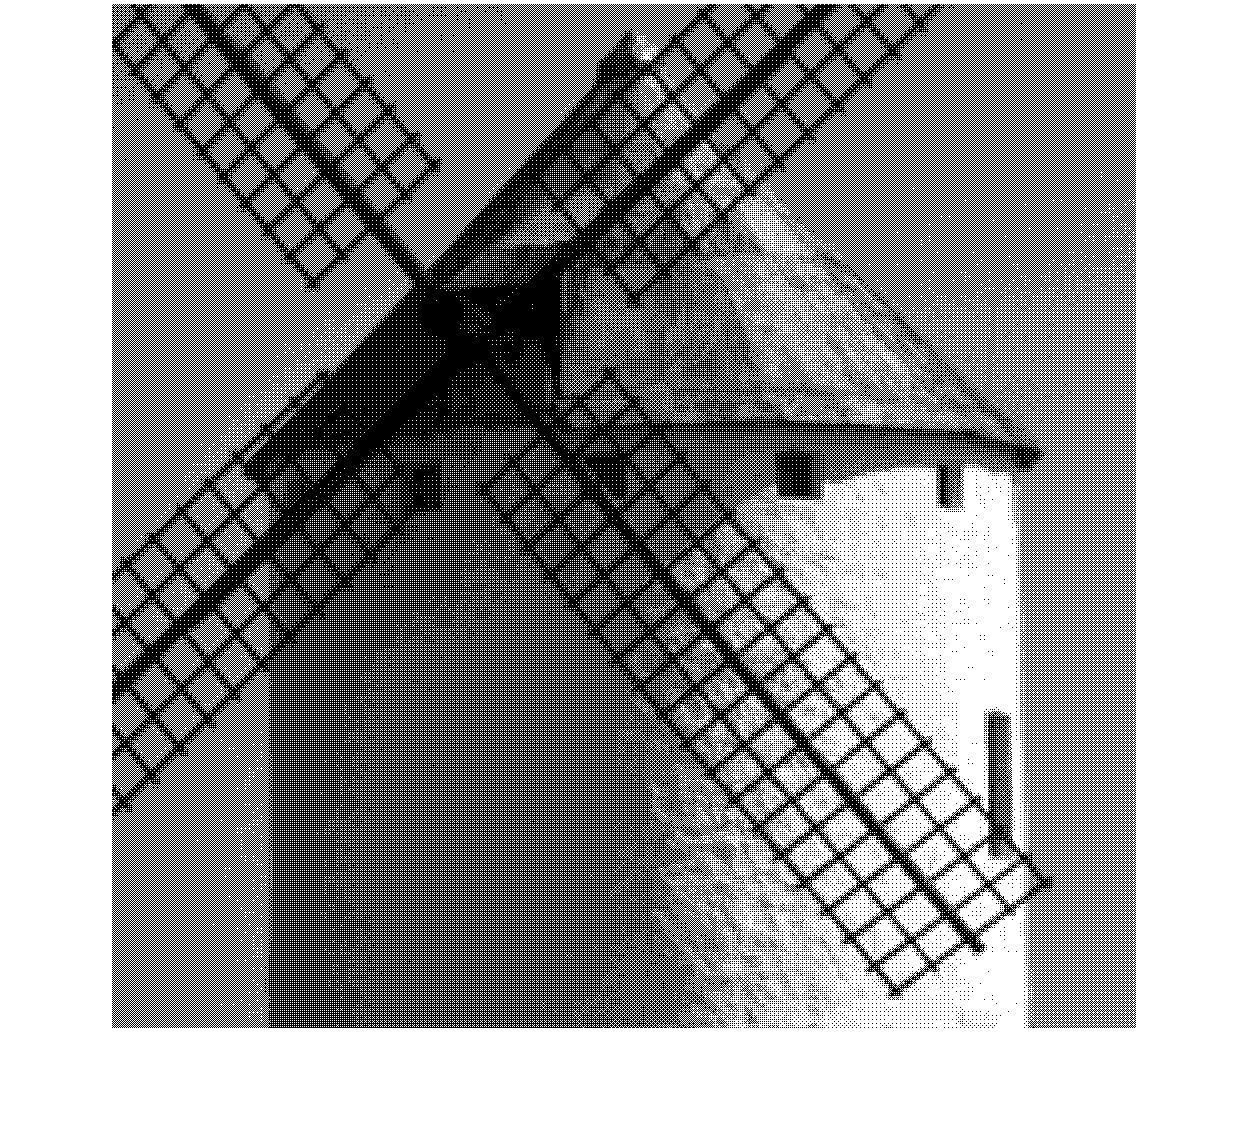

%2.4
b24 = tabellrast3(bild);
imshow(b24);


%eftersom att varje 2x2 fördubblas så fördubblas också bilden?
%använder 2 gråtoner, 0 och 1.

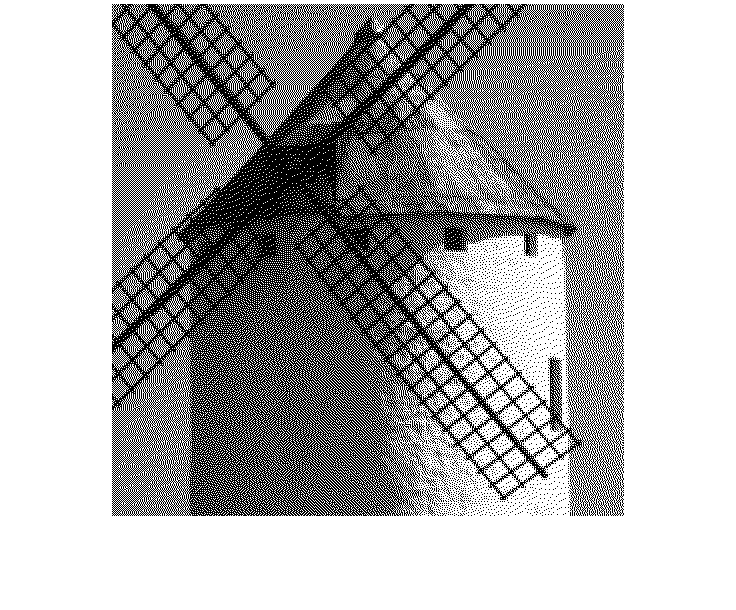

%3.1
filt = [0 0 7;
        3 5 1]/16;
b31 = errordif(bild,filt);
imshow(b31);

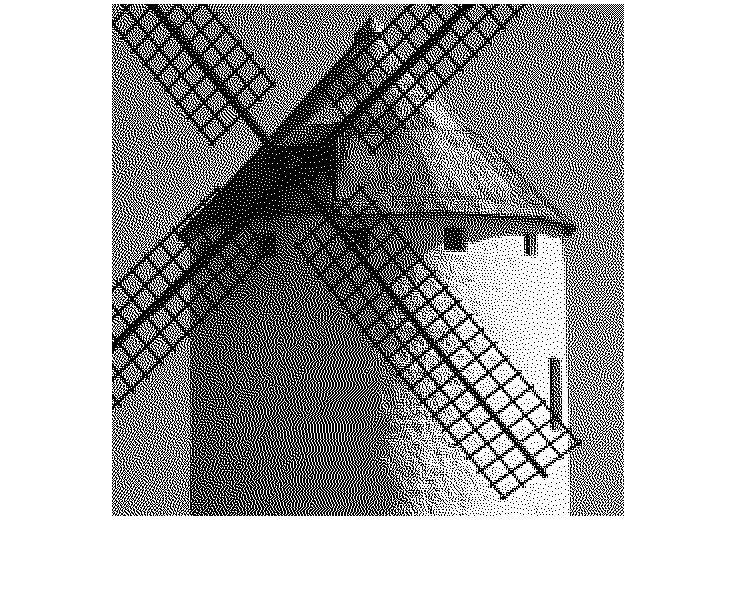

%3.2

filt = [0 0 0 7 5;
        3 5 7 5 3;
        1 3 5 3 1]/48;
b32 = errordif(bild,filt);
imshow(b32);


% 
% filt = [0 0 0 8 4;
%         2 4 8 4 2;
%         1 2 4 2 1]/42;
% b33 = errordif(bild,filt);
% imshow(b33);

%3.3

% i b31 ser vi mer ljusa toner som träder fram
% b32 ger mindre brus

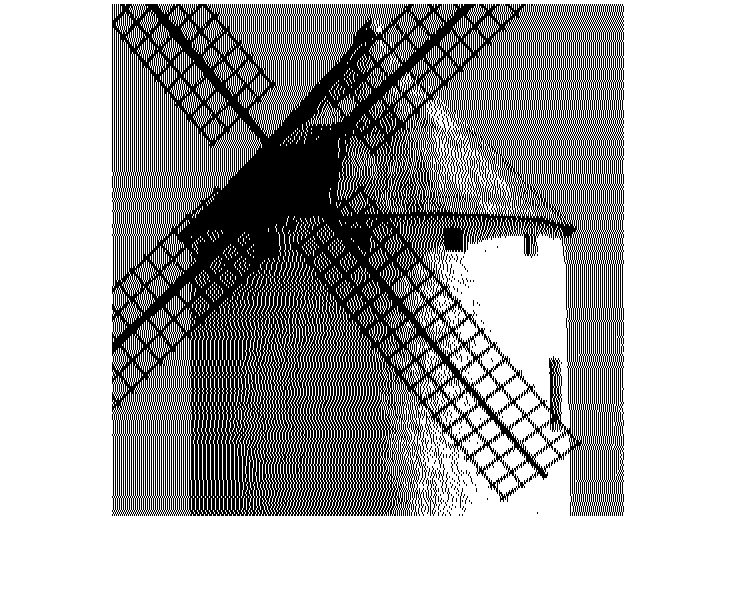

%3.4
% använder en nivå
filt = [0 0 6;
        0 0 0]/10;
b341 = errordif(bild,filt);
imshow(b341);

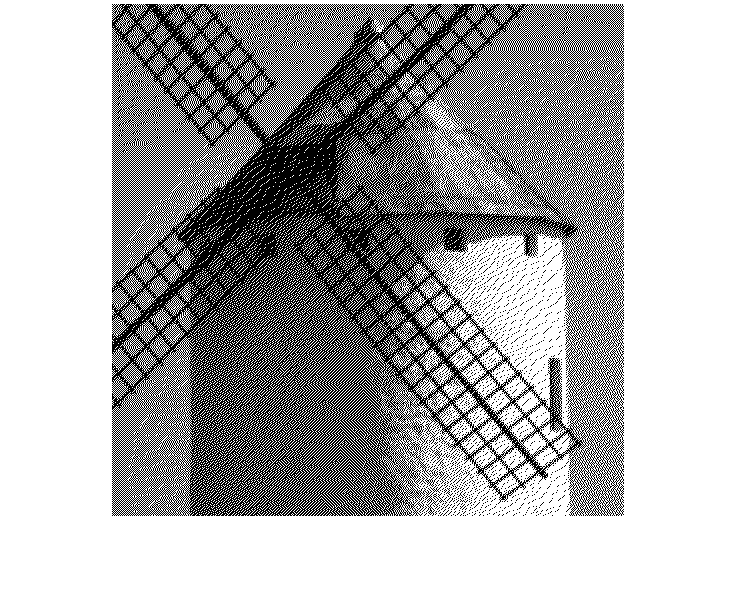


%använder två nivåer
filt = [0 0 6;
        0 4 0]/10;
b342 = errordif(bild,filt);
imshow(b342);

%3.5
% b31 
% All pixels in the original image hold 0.1, illustrating
% the directional hysteresis.
% b32 
% All pixels in the original image hold 0.4, illustrating the
% correlated artifacts.

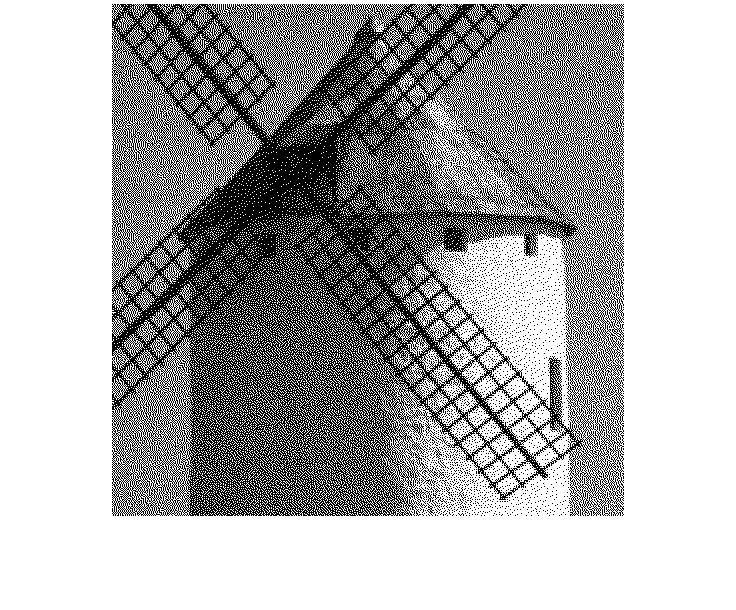

%3.6
k = 0.3; %chosen value
brus1 = rand(512)-0.5; %brusbild utan variabel
brus = brus1 * k; %brusbild med variabel

b361 = brus + bild; %resultat med bild

filt = [0 0 7;
        3 5 1]/16;
b36 = errordif(b361,filt); %felsöker
        imshow(b36);

%4.0
b40 = imcdp(bild);

imcdp
----------
here13
here14
here14
9% done
----
17% done
----
26% done
----
26% done
----
34% done
----
43% done
----
52% done
----
60% done
----
69% done
----
78% done
----
78% done
----
86% done
----
95% done
----
here9
here10
here8
here6
here17
here4
here5
here7
here18
here16
here11
here3
here2
here15
here12
here1


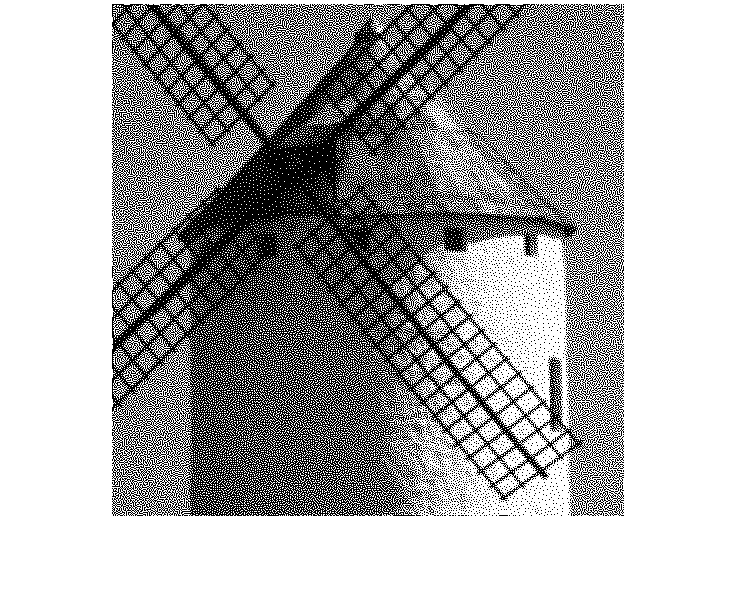

imshow(b40);

%5.1
%difference between original and noise
b11_sk = bild - b11;
b31_sk = bild - b31;
b40_sk = bild - b40;
%using function
b11_noise = mysnr(bild, b11_sk);
b31_noise = mysnr(bild, b31_sk);
b40_noise = mysnr(bild, b40_sk);

b11_noise

b11_noise = 2.5915

b31_noise

b31_noise = 0.8801

b40_noise

b40_noise = 0.8068

imshow(b11);

imshow(b31);

imshow(b40);

%5.2
b11_snr =  snr_filter(bild, b11_sk);

Unrecognized function or variable 'b11_sk'.

b31_snr =  snr_filter(bild, b31_sk);
b40_snr =  snr_filter(bild, b40_sk);
b11_snr
b31_snr
b40_snr

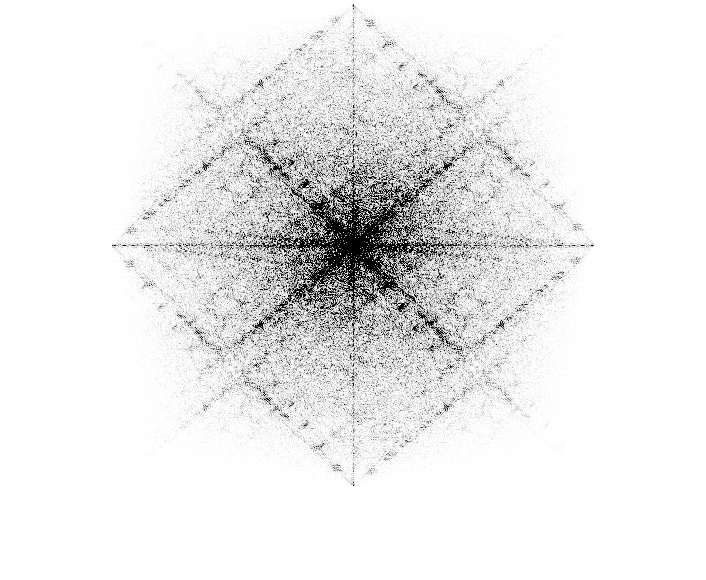

%5.3
b11_QNS = QNS(bild, b11);

b31_QNS = QNS(bild, b31);

Unrecognized function or variable 'b31'.

b40_QNS = QNS(bild, b40);
b11_QNS
b31_QNS
b40_QNS

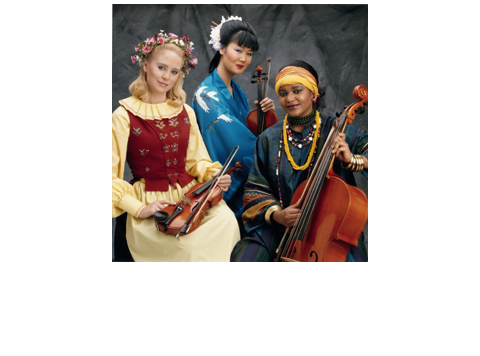

%fargraster

fargbild= imread('musicians.tif');
fargbild = double(fargbild)/255;
imshow(fargbild);


imFarg = fargraster(fargbild,'errordif');
erFarg = fargraster(fargbild,'imcdp');

imcdp
----------
37% done
----
74% done
----
here1
here16
here9
here15
here8
here10
here6
here7
here5
here17
here18
here11
here4
here14
here3
here2
here12
here14
here13
imcdp
----------
44% done
----
here1
here14
88% done
----
here17
here9
here5
here10
here8
here15
here7
here4
here3
here18
here6
here16
here11
here2
here12
here13
here14
imcdp
----------
here14
here1
here15
here16
50% done
----
50% done
----
here17
here14
here9
here8
here3
here18
here6
here2
here4
100% done
----
here10
here7
here5
here11
here13
here12


felFarg = fargraster(fargbild,'hej');

Not working


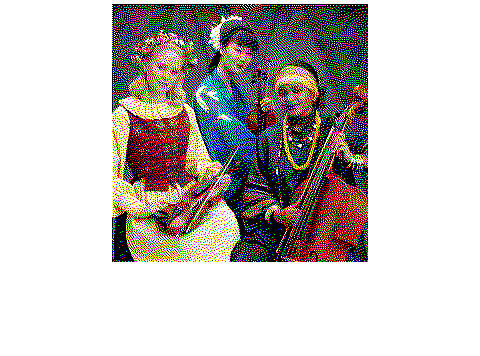


imshow(imFarg);

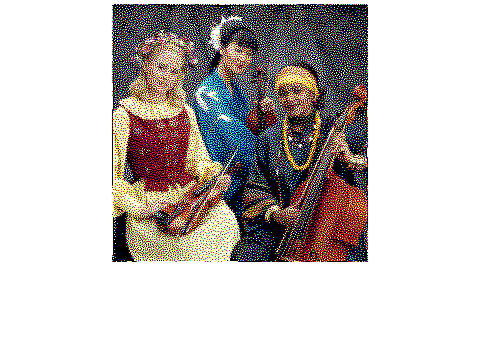

imshow(erFarg);

%imshow(felFarg);